## Module 1 project 3

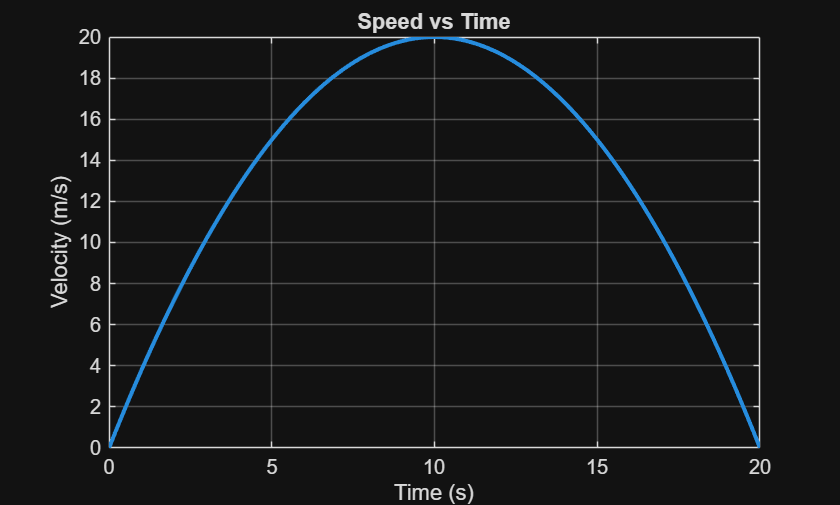

%% Time vector (0 to 20 seconds in 0.2 s increments)
t = 0:0.2:20;

%% Velocity model v(t) = -0.2(t - 10)^2 + 20
% This is a concave-down parabola with a peak at t = 10 seconds.
v = -0.2*(t - 10).^2 + 20;

%% Plot velocity vs time
plot(t, v, 'LineWidth', 2)
xlabel('Time (s)')
ylabel('Velocity (m/s)')
grid on
title('Speed vs Time')


%% Numerical acceleration using finite differences
dv = diff(v);      % change in velocity
dt = diff(t);      % change in time (constant 0.2)
a  = dv ./ dt;     % acceleration approximation
a = round(a, 4);   % round for cleaner output

%% Midpoints for acceleration plot
% Acceleration values lie between velocity samples,
% so we compute midpoint times for proper alignment.
t_mid = (t(1:end-1) + t(2:end)) / 2;
disp(t_mid)

    0.1000    0.3000    0.5000    0.7000    0.9000    1.1000    1.3000    1.5000    1.7000    1.9000    2.1000    2.3000    2.5000    2.7000    2.9000    3.1000    3.3000    3.5000    3.7000    3.9000    4.1000    4.3000    4.5000    4.7000    4.9000    5.1000    5.3000    5.5000    5.7000    5.9000    6.1000    6.3000    6.5000    6.7000    6.9000    7.1000    7.3000    7.5000    7.7000    7.9000    8.1000    8.3000    8.5000    8.7000    8.9000    9.1000    9.3000    9.5000    9.7000    9.9000   10.1000   10.3000   10.5000   10.7000   10.9000   11.1000   11.3000   11.5000   11.7000   11.9000   12.1000   12.3000   12.5000   12.7000   12.9000   13.1000   13.3000   13.5000   13.7000   13.9000   14.1000   14.3000   14.5000   14.7000   14.9000   15.1000   15.3000   15.5000   15.7000   15.9000   16.1000   16.3000   16.5000   16.7000   16.9000   17.1000   17.3000   17.5000   17.7000   17.9000   18.1000   18.3000   18.5000   18.7000   18.9000   19.1000   19.3000   19.5000   19.7000   19.9000

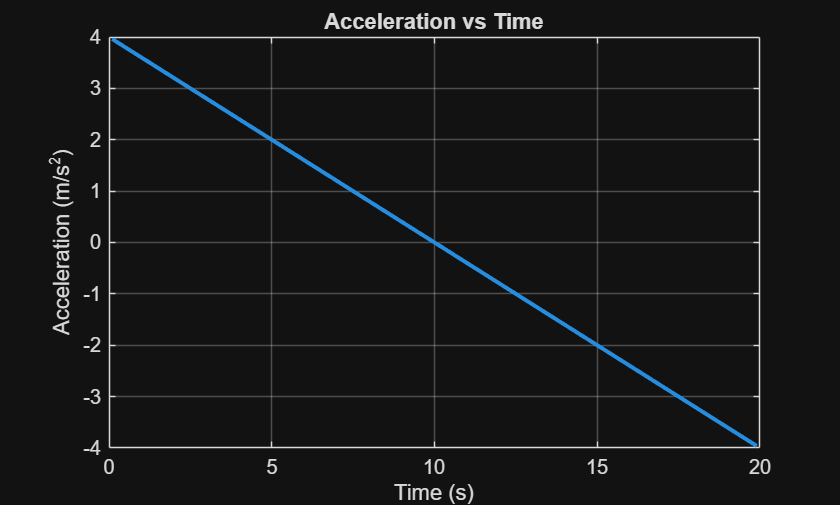


%% Plot acceleration vs time
figure;
plot(t_mid, a, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
grid on;
title('Acceleration vs Time');


%% Find maximum speed and corresponding time
[maxSpeed, idx] = max(v);   % max velocity and its index
t_max = t(idx);             % time of max velocity

fprintf('Max speed occurs at t = %.2f seconds\n', t_max);

Max speed occurs at t = 10.00 seconds



%% Find acceleration closest to the time of max speed
% We compare t_mid to t_max and pick the nearest acceleration sample.
[~, idx_a] = min(abs(t_mid - t_max));

fprintf('Acceleration near that time is approximately %.4f m/s^2\n', a(idx_a));

Acceleration near that time is approximately 0.0400 m/s^2
